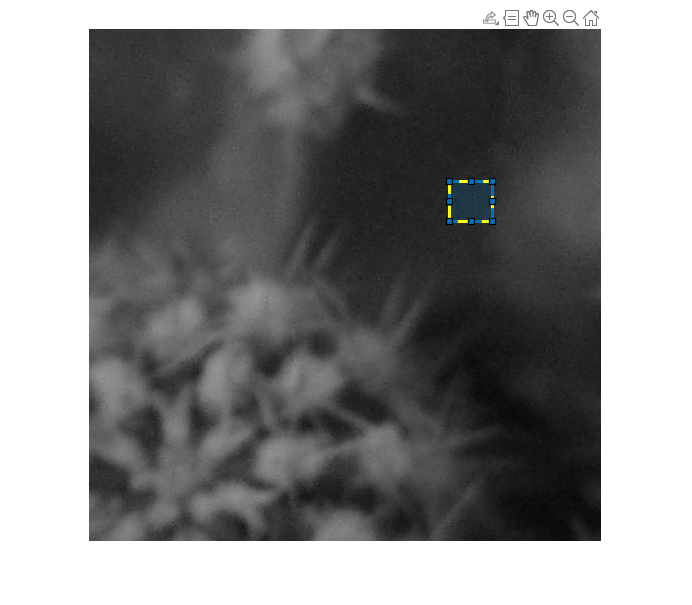

%Decide what image series to use
%'TestImages\Geode\';
%'TestImages\Cactus\';
%'TestImages\Card\';

%Create a vector with the names
%pictures = ["0", '1', '2', '3','4', '5', '6','7', '8', '9','10', '11', '12','13', '14', '15', '16', '17', '18', '19', '20', '21', '22', '23', '24', '25', '26'];

%Cactus only
pictures = ["1", '2', '3','4', '5', '6','7', '8', '9','10', '11', '12','13', '14', '15', '16', '17', '18', '19', '20', '21', '22', '23', '24', '25', '26'];

%im_box = imread('TestImages\Geode\0.jpg');
im_box = imread('TestImages\Cactus\1.jpg');
%im_box = imread('TestImages\Card\0.jpg');
imshow(im_box)
roi = drawrectangle('StripeColor','y');


%Set the block size we want to use
N = roi.Vertices(2,2) -  roi.Vertices(1,2); 
M = roi.Vertices(3,2) -  roi.Vertices(4,2); 

i =  round((roi.Vertices(1,1) + roi.Vertices(3,1))/2); 
j =  round((roi.Vertices(1,1) + roi.Vertices(1,2))/2);

roi_temp = roi.Position;


%SML
smlRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    smlRes(x) = SML(im_temp); 
end


%EOL
eolRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    eolRes(x) = EOL(im_temp);
end


%EOG
eogRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    eogRes(x) = EOG(im_temp);
end


%SF 
sfRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    sfRes(x) = SF(im_temp);
end


%Tenengrad
tenRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    tenRes(x) = Tenengrad(im_temp);
end



%Variance
varRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_temp = imcrop(im_x,roi_temp);
    varRes(x) = Variance(im_temp);
end


% Spectrum band ratio
sbrRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_x = im2gray(im_x);
    im_temp = imcrop(im_x,roi_temp);
    im_temp = abs(fftshift(fft2(im_temp)));
    cY=floor(N/2+1);
    cX=floor(M/2+1);
    im_temp(cY,cX)=0;
    sbrRes(x) = SBR(im_temp);
end


% Spectrum
specRes = zeros(1, length(pictures));

for x = 1:length(pictures)
    im_x = imread('TestImages\Cactus\' + pictures(x) + '.jpg');
    im_x = im2double(im_x);
    im_x = im2gray(im_x);
    im_temp = imcrop(im_x,roi_temp);
    im_temp = abs(fftshift(fft2(im_temp)));
    cY=floor(N/2+1);
    cX=floor(M/2+1);
    im_temp(cY,cX)=0;
    specRes(x) = Spectrum(im_temp);
end

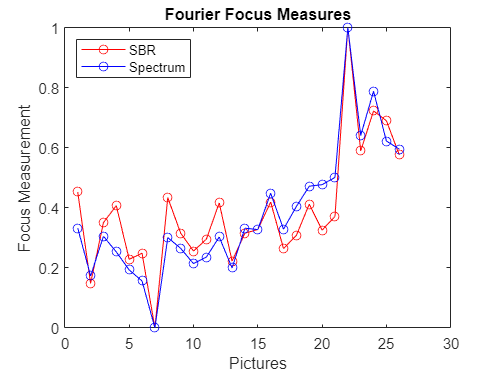

%Plot Fourier Focus Measures
sbrRes = normalize(sbrRes,'range');
specRes = normalize(specRes,'range');
plot(sbrRes,'-o', 'Color','red','MarkerIndices',1:1:length(sbrRes))
hold on
plot(specRes,'-o', 'Color','blue','MarkerIndices',1:1:length(specRes))

title('Fourier Focus Measures')
legend('SBR', 'Spectrum', 'Location', 'northwest')
xlabel('Pictures') 
ylabel('Focus Measurement') 
hold off

%Normalize all vectors
smlRes = normalize(smlRes,'range');
eolRes = normalize(eolRes,'range');
eogRes = normalize(eogRes,'range');
sfRes = normalize(sfRes,'range');
tenRes = normalize(tenRes,'range');
varRes = normalize(varRes,'range');

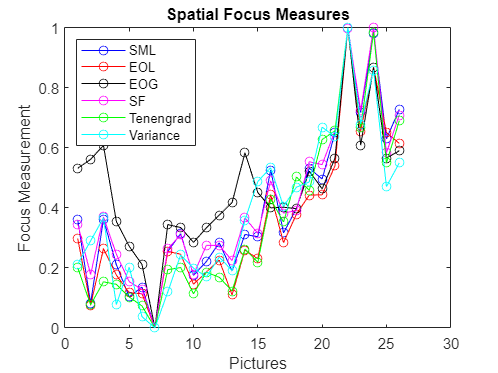

%Plot Spatial Focus Measures
plot(smlRes,'-o', 'Color','blue','MarkerIndices',1:1:length(smlRes))
hold on
plot(eolRes,'-o','Color','red','MarkerIndices',1:1:length(eolRes))
plot(eogRes,'-o','Color','black','MarkerIndices',1:1:length(eogRes))
plot(sfRes,'-o','Color','magenta','MarkerIndices',1:1:length(sfRes))
plot(tenRes,'-o','Color','green','MarkerIndices',1:1:length(tenRes))
plot(varRes,'-o','Color','cyan','MarkerIndices',1:1:length(varRes))
hold off

title('Spatial Focus Measures')
legend('SML', 'EOL', 'EOG', 'SF', 'Tenengrad', 'Variance', 'Location', 'northwest')
xlabel('Pictures') 
ylabel('Focus Measurement') 